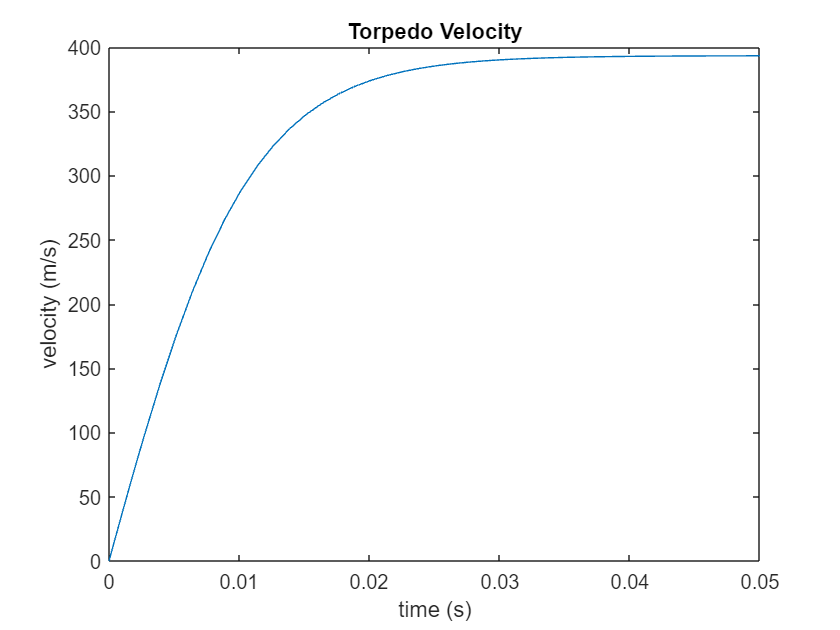

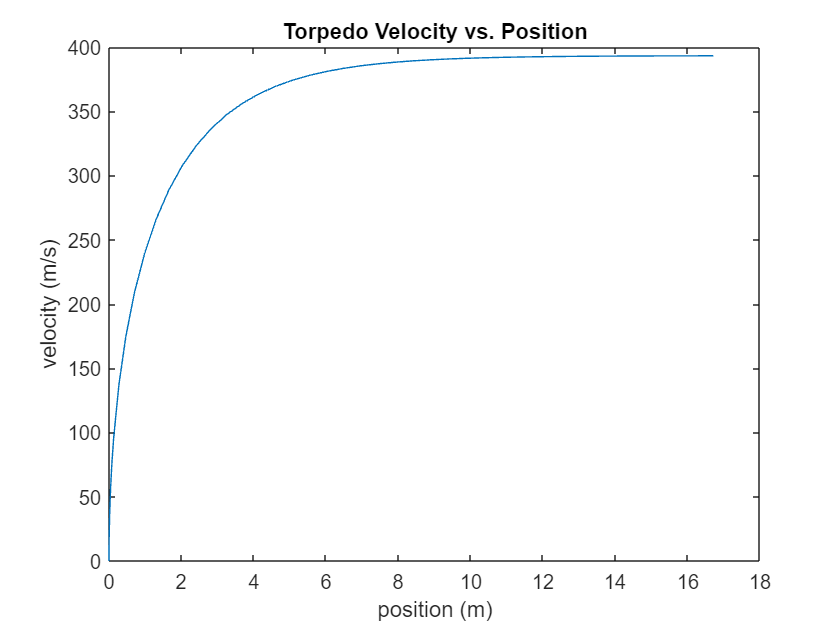

   60.4822



torpedo()

function torpedo()
    
    %unit conversions 
    atm2pa = 101325;
    in2m = 0.0254;
    ft2m = in2m * 12;
    gal2m3 = 0.00378541;
    psi2pa = 6894.76;
    min2s = 60;
    cv_units = gal2m3/(min2s*sqrt(psi2pa));
    
    %varibles
    % v = v_1
    syms P_0 P_amb rho K_L1 K_L2 L_1 L_2 D_1 A_1 A_5 SG C_v f_1 f_2 m v

    m = 0.0311; %kg
    P_0 = 5.44 * atm2pa; %Pa %80 psi
    P_amb = 1 * atm2pa; %Pa
    rho = 1.225; %kg/m^3
    D_1 = .25 * in2m; %m
    D_5 = 0.75 * in2m; %m
    D_0 = 1 * in2m; %m    
    K_L1 = 1; %unitless
    K_L2 = (1 - D_1/D_5).^2; %unitless
    L_1 = 10 * ft2m; %m 
    L_2 = 10 * ft2m; %m
    A_1 = D_1.^2*pi/4; %m^2
    A_5 = D_5.^2*pi/4; %m^2
    mu = 1.85e-05; %Ns/m^2
    SG = 1.03e-03; %unitless
    C_v = 1 * cv_units; %C_v^2 = m^7/kg
    f = 64*mu/(rho*D_1); %m/s
    f_1 = f; %m/s
    f_2 = f; %m/s

    function dvdt = eqn3(~,v)
        dvdt = A_5.^2/(m*A_1) * (P_0 -P_amb - v.^2/2 * (rho*K_L1 + rho*f_1*L_1/(D_1*v) + 2*SG*A_1.^2/ C_v.^2+ rho*f_2*L_2/(D_1*v) + rho*(A_1/A_5)^2 + rho*K_L2));

    end

    t_span = [0 0.05];
    inital_v = 0.00005;

    [t,v] = ode45(@(t,v)eqn3(t,v), t_span, inital_v);
    
    figure(1)
    plot(t,v);
    xlabel('time (s)');
    ylabel('velocity (m/s)');
    title('Torpedo Velocity');

    %% Obtain position vector
    positions = zeros(1, length(t));
    for i = 2:length(t)
        positions(i) = trapz(t(1:i), v(1:i));
    end

    figure(2)
    plot(positions,v);
    xlabel('position (m)');
    ylabel('velocity (m/s)');
    title('Torpedo Velocity vs. Position');

    strokeLength = 2; %in
    strokeLength = strokeLength * in2m; %in
    exitVelocity = interp1(positions,v,strokeLength); %m/s
    disp(exitVelocity)

   
end